# Random Forests

## Rationale: wisdom of crowds

**Random forests** describes an algorithm that aggregates predictions from multiple "good" decision trees. This builds on the concept of "wisdom of crowds", where the aggregated answer from hundreds of guesses is sometimes close to the actual answer.

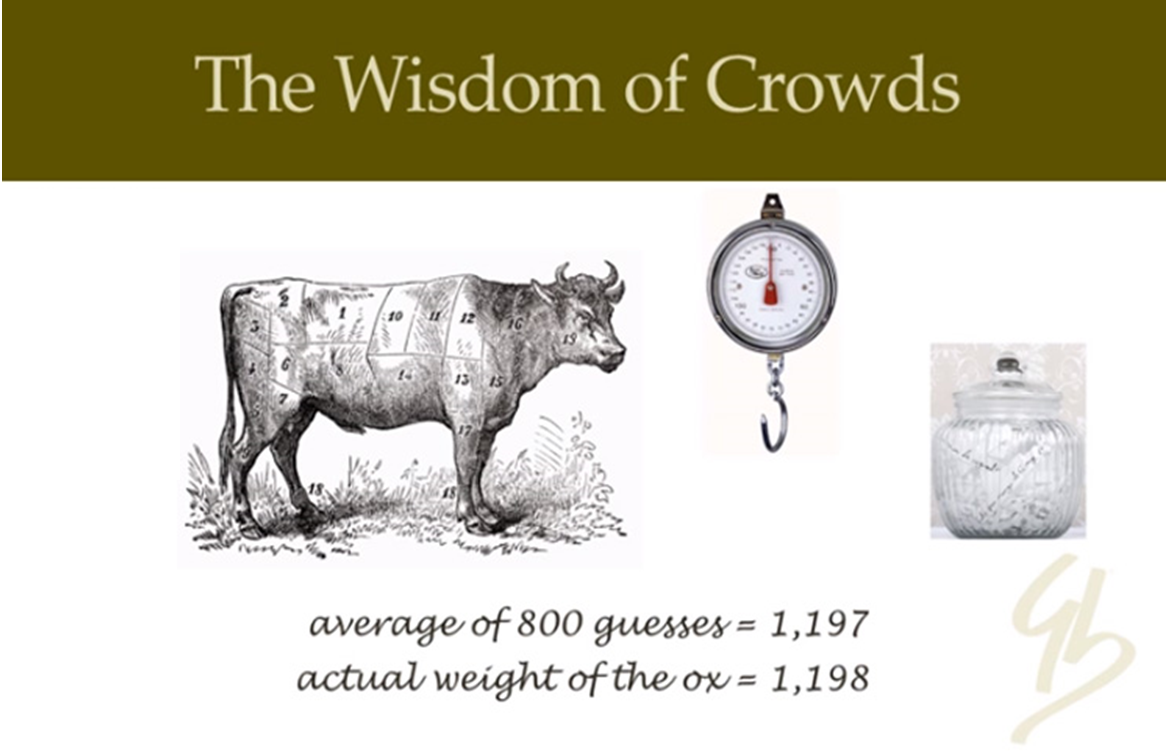

## Building a random forests model

Random forests is an **ensemble** method, where the ensemble is composed by a group of predictors (trees). When building a random forests model, predictions from hundreds of decision trees are combined by majority voting (for classification) or averaging (for regression). 

### How do we build different trees using the same data? 

A common method is **bootstrap sampling** (**bagging**), where each decision tree is trained with a random subset of the training data. We can then assess the **out-of-bag (OOB) estimate** to evaluate how our model performed. The OOB estimate for a sample is determined by aggregating predictions from all trees that were not trained using the sample. 

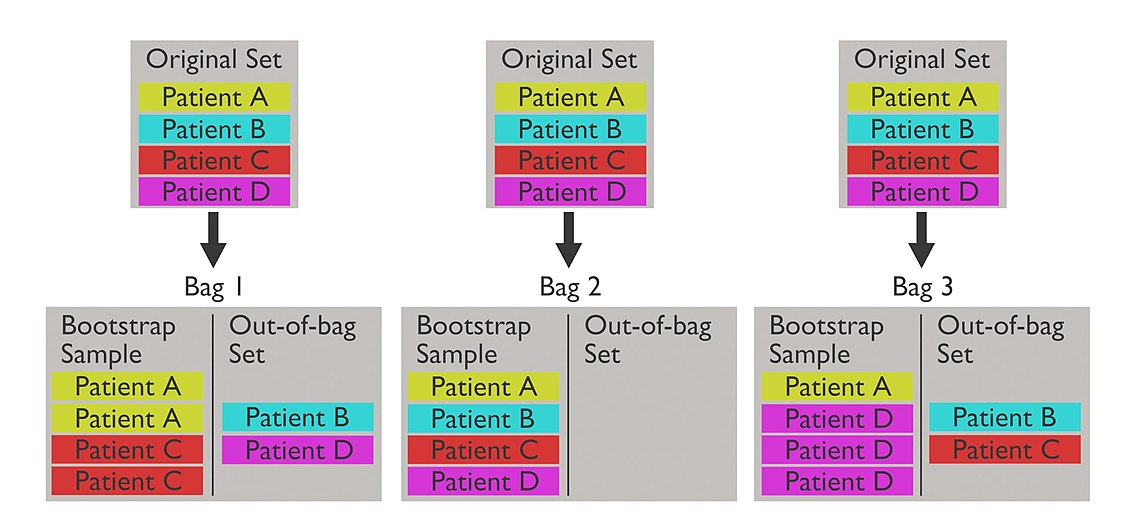

### Hyperparameter optimization

The same set of hyperparameters considered for decision trees can also be tuned when building a random forests model. Additionally, we can tune the number of trees that make up our forest.

### Feature importance

For a random forests model, we can measure the relative importance of each feature for accurately predicting the output. **Feature importance** can be quantified in many ways - a common method is to assess how the prediction accuracy changes when a feature is not used in the model. 

## In-class example: predicting diabetes using the Framingham dataset

We'll build upon the decision tree model we developed last time to predict diabetes. Let's first load the dataset, define our inputs/output, and subset them into training and testing sets:

% Load the dataset
fram = readtable('frmgham2.xls');

% Extract all features except diabetes (column 10)
X = fram(:, [1:9, 11:14]);

% Define output variable (diabetes)
Y = fram.DIABETES;

% Subset data into training/testing sets via 30% holdout
idx = crossvalind('HoldOut', Y, 0.3); 
[Xtrain, Ytrain, Xtest, Ytest] = deal(X(idx, :), Y(idx), X(~idx, :), Y(~idx)); 

We'll use the built-in `TreeBagger` function to develop a random forests model with 100 trees:

RFmodel = TreeBagger(100, Xtrain, Ytrain)

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:            [8139x13]
                    Training Y:             [8139x1]
                        Method:       classification
                 NumPredictors:                   13
         NumPredictorsToSample:                    4
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    0
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '0'             '1'

  Properties, Methods


We can view individual trees in our RF model by inspecting the `Trees` field of the model: 

% View tree 1
view(RFmodel.Trees{1})

Decision tree for classification
  1  if SYSBP<186.75 then node 2 elseif SYSBP>=186.75 then node 3 else 0
  2  if BPMEDS<0.5 then node 4 elseif BPMEDS>=0.5 then node 5 else 0
  3  if GLUCOSE<138.5 then node 6 elseif GLUCOSE>=138.5 then node 7 else 0
  4  if TOTCHOL<217.5 then node 8 elseif TOTCHOL>=217.5 then node 9 else 0
  5  if SYSBP<152.75 then node 10 elseif SYSBP>=152.75 then node 11 else 0
  6  if GLUCOSE<125 then node 12 elseif GLUCOSE>=125 then node 13 else 0
  7  class = 1
  8  if GLUCOSE<129.5 then node 14 elseif GLUCOSE>=129.5 then node 15 else 0
  9  if AGE<57.5 then node 16 elseif AGE>=57.5 then node 17 else 0
 10  if GLUCOSE<128 then node 18 elseif GLUCOSE>=128 then node 19 else 0
 11  if GLUCOSE<141.5 then node 20 elseif GLUCOSE>=141.5 then node 21 else 0
 12  if GLUCOSE<96 then node 22 elseif GLUCOSE>=96 then node 23 else 0
 13  if SYSBP<216.25 then node 24 elseif SYSBP>=216.25 then node 25 else 0
 14  if SYSBP<152.75 then node 26 elseif SYSBP>=152.75 then node 27 else

% View tree 2
view(RFmodel.Trees{2})

Decision tree for classification
  1  if TOTCHOL<631.5 then node 2 elseif TOTCHOL>=631.5 then node 3 else 0
  2  if AGE<67.5 then node 4 elseif AGE>=67.5 then node 5 else 0
  3  class = 1
  4  if SYSBP<154.75 then node 6 elseif SYSBP>=154.75 then node 7 else 0
  5  if GLUCOSE<166 then node 8 elseif GLUCOSE>=166 then node 9 else 0
  6  if BPMEDS<0.5 then node 10 elseif BPMEDS>=0.5 then node 11 else 0
  7  if GLUCOSE<134.5 then node 12 elseif GLUCOSE>=134.5 then node 13 else 0
  8  if GLUCOSE<102.5 then node 14 elseif GLUCOSE>=102.5 then node 15 else 0
  9  class = 1
 10  if GLUCOSE<142 then node 16 elseif GLUCOSE>=142 then node 17 else 0
 11  if GLUCOSE<126.5 then node 18 elseif GLUCOSE>=126.5 then node 19 else 0
 12  if GLUCOSE<97.5 then node 20 elseif GLUCOSE>=97.5 then node 21 else 0
 13  if GLUCOSE<147.5 then node 22 elseif GLUCOSE>=147.5 then node 23 else 1
 14  if GLUCOSE<53.5 then node 24 elseif GLUCOSE>=53.5 then node 25 else 0
 15  if DIABP<73.25 then node 26 elseif DIABP>=73.2

### Assess out-of-bag (OOB) error

Let's build our model again, and this time we'll inpect how the OOB error changes with the number of trees: 

% Define 'OOBPrediction' as 'on'
RFmodel = TreeBagger(100, Xtrain, Ytrain, 'OOBPrediction', 'on')

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:            [8139x13]
                    Training Y:             [8139x1]
                        Method:       classification
                 NumPredictors:                   13
         NumPredictorsToSample:                    4
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '0'             '1'

  Properties, Methods


% Evaluate the OOB error for each tree
err = oobError(RFmodel); 
table([1:100]', err, 'VariableNames', {'Trees', 'OOB Error'})

ans = 100×2 table
    Trees    OOB Error
    _____    _________

      1      0.052095 
      2      0.053815 
      3      0.049638 
      4      0.048286 
      5      0.045706 
      6      0.043986 
      7       0.04288 
      8       0.04116 
      9        0.0403 
     10      0.039194 
     11      0.038703 
     12      0.037842 
     13      0.036737 
     14      0.035754 
     15         0.036 
     16      0.036122 


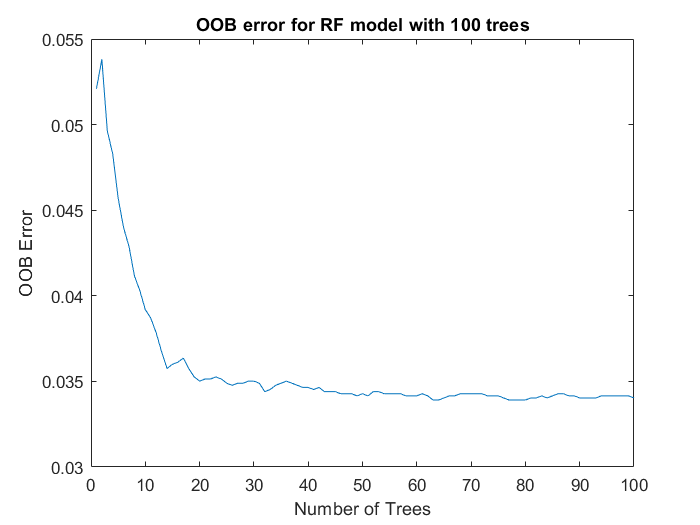

% Visualize how error changes as we add more trees
figure
plot(err)
xlabel('Number of Trees')
ylabel('OOB Error')
title('OOB error for RF model with 100 trees')

### Customize hyperparameters

We can also tune the same hyperparameters available with decision trees: 

% Set `MinLeafSize' to 10
RFmodel = TreeBagger(100, Xtrain, Ytrain, 'MinLeafSize', 10, 'OOBPrediction', 'on')

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:            [8139x13]
                    Training Y:             [8139x1]
                        Method:       classification
                 NumPredictors:                   13
         NumPredictorsToSample:                    4
                   MinLeafSize:                   10
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '0'             '1'

  Properties, Methods


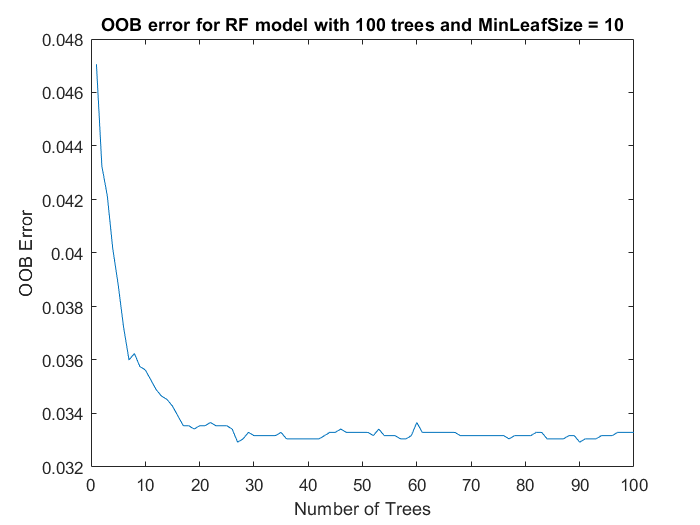

err = oobError(RFmodel); 
figure; plot(err)
xlabel('Number of Trees')
ylabel('OOB Error')
title('OOB error for RF model with 100 trees and MinLeafSize = 10')

### Assess RF model feature importance

We can assess feature importance by setting the `OOBPredictorImportance` parameter to `on`: 

% Assess feature importance
RFmodel = TreeBagger(100, Xtrain, Ytrain, 'MinLeafSize', 10, 'OOBPrediction', 'on', 'OOBPredictorImportance', 'on')

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:            [8139x13]
                    Training Y:             [8139x1]
                        Method:       classification
                 NumPredictors:                   13
         NumPredictorsToSample:                    4
                   MinLeafSize:                   10
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             '0'             '1'

  Properties, Methods


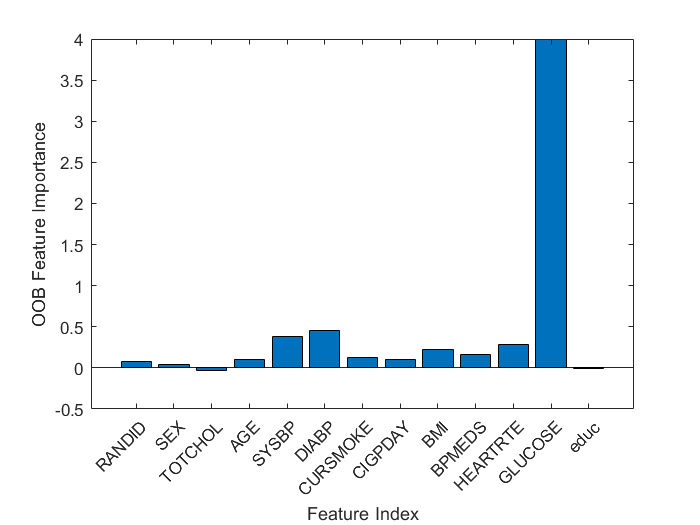

% Visualize feature importance with a bar plot
figure
bar(RFmodel.OOBPermutedPredictorDeltaError)
xlabel('Feature Index')
ylabel('OOB Feature Importance')
xticklabels(X.Properties.VariableNames)
xtickangle(45)

### Assess RF model performance

We'll now assess our RF model performance using metrics for a classifier: 

% Determine predictions for test set
Ypred = predict(RFmodel, Xtest); 

% Convert predictions to double array (default = cell array)
Ypred = str2double(Ypred); 

% Assess overall accuracy and precision + recall for predicting diabetes
accuracy = mean(Ypred == Ytest)

accuracy = 0.9633

tp = sum(Ypred == 1 & Ytest == 1); 
fp = sum(Ypred == 1 & Ytest == 0); 
fn = sum(Ypred == 0 & Ytest == 1); 
precision = tp / (tp + fp)

precision = 0.7246

recall = tp / (tp + fn)

recall = 0.3145

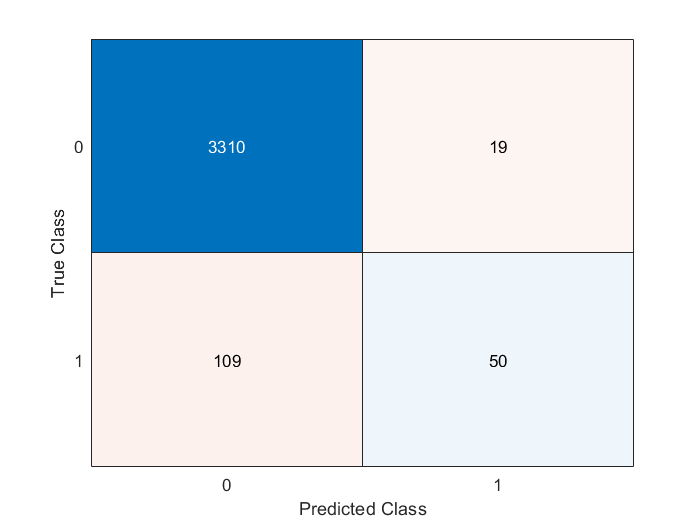

% Visualize confusion chart
confusionchart(Ytest, Ypred)

Question: How does this compare to our previous DT classifier? 

## Another function to build RF models in MATLAB

Alternatively, we can use the `fitcensemble` function to build an RF model: 

% Build RF model (default number of trees = 100)
RFMdl = fitcensemble(Xtrain, Ytrain); 

`RFMdl = `

  [`classreg.learning.classif.ClassificationEnsemble`](matlab: helpPopup classreg.learning.classif.ClassificationEnsemble)

`           PredictorNames: {'RANDID'  'SEX'  'TOTCHOL'  'AGE'  'SYSBP'  'DIABP'  'CURSMOKE'  'CIGPDAY'  'BMI'  'DIABETES'  'BPMEDS'  'HEARTRTE'  'GLUCOSE'  'educ'}`

`             ResponseName: 'Y'`

`    CategoricalPredictors: []`

`               ClassNames: [0    1]`

`           ScoreTransform: 'none'`

`          NumObservations: 8139`

`               NumTrained: 100`

`                   Method: 'LogitBoost'`

`             LearnerNames: {'Tree'}`

`     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'`

`                  FitInfo: [100×1 double]`

`       FitInfoDescription: {2×1 cell}`

  [`Properties`](matlab: properties('classreg.learning.classif.ClassificationEnsemble'))`, `[`Methods`](matlab: methods('classreg.learning.classif.ClassificationEnsemble'))

% View tree 1
view(RFMdl.Trained{1}.CompactRegressionLearner)

Decision tree for regression
 1  if GLUCOSE<139 then node 2 elseif GLUCOSE>=139 then node 3 else 1.81767
 2  if GLUCOSE<113.5 then node 4 elseif GLUCOSE>=113.5 then node 5 else 1.89629
 3  if GLUCOSE<166 then node 6 elseif GLUCOSE>=166 then node 7 else -1.2987
 4  if TOTCHOL<631.5 then node 8 elseif TOTCHOL>=631.5 then node 9 else 1.92163
 5  if RANDID<8.53521e+06 then node 10 elseif RANDID>=8.53521e+06 then node 11 else 1.19672
 6  if BMI<29.165 then node 12 elseif BMI>=29.165 then node 13 else -0.37037
 7  if GLUCOSE<182.5 then node 14 elseif GLUCOSE>=182.5 then node 15 else -1.8
 8  if BPMEDS<0.5 then node 16 elseif BPMEDS>=0.5 then node 17 else 1.92544
 9  fit = -2
10  fit = 1.36842
11  if BMI<27.37 then node 18 elseif BMI>=27.37 then node 19 else 0.171429
12  fit = 0.0487805
13  fit = -1.69231
14  if DIABP<61 then node 20 elseif DIABP>=61 then node 21 else -1.25926
15  fit = -2
16  fit = 1.93811
17  fit = 1.80769
18  fit = 0.909091
19  fit = -1.07692
20  fit = 2
21  fit = -1.52



### Why use fitcensemble? 

An advantage to using `fitcensemble` is that just like `fitctree`, we can automatically optimize hyperparameters by setting `OptimizeHyperparameters` to `auto`: 

%%%%% DO NOT RUN (TAKES > 6 MINUTES TO COMPLETE) %%%%%%
% RFMdl_opt = fitcensemble(Xtrain, Ytrain, 'OptimizeHyperparameters', 'auto')

However, a drawback is that model training could take a long time depending on the size of the training data. In cases when `fitcensemble` with automated hyperparameter optimization takes a long time to compute, `TreeBagger` is preferrable since it can be used with muticore machines (which allow parallel computing). 

### Assess model performance

% Determine predictions for test set
Ypred = predict(RFMdl, Xtest); 

% Assess overall accuracy and precision + recall for predicting diabetes
accuracy = mean(Ypred == Ytest)

accuracy = 0.9530

tp = sum(Ypred == 1 & Ytest == 1); 
fp = sum(Ypred == 1 & Ytest == 0); 
fn = sum(Ypred == 0 & Ytest == 1); 
precision = tp / (tp + fp)

precision = 0.4766

recall = tp / (tp + fn)

recall = 0.3208

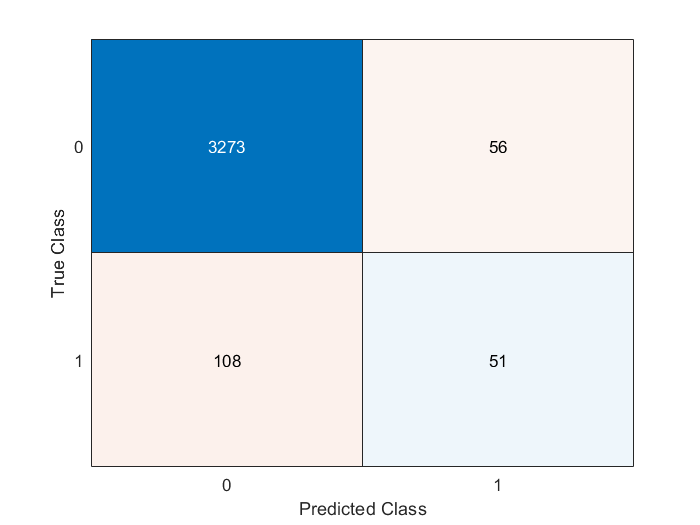

% Visualize confusion chart
confusionchart(Ytest, Ypred)

Question: How did this RF model compare to our previous one? 

## Regression-based RF

Regression-based random forests models can be built using the `fitrensemble` function or using the `TreeBagger` function while setting `Method` to `regression. `The code below builds a regression-based RF model using `TreeBagger` to predict age based on patient data from the Framingham dataset: : 

% Define input/output and training/testing sets
[X, Y] = deal(fram(:, [1:3 5:11]), fram.AGE);   % define input/output
idx = crossvalind('HoldOut', numel(Y), 0.3);    % split to train/test
[Xtrain, Ytrain, Xtest, Ytest] = deal(X(idx, :), Y(idx), X(~idx, :), Y(~idx)); 

% Build regression model with automated hyperparameter optimization
regTree = TreeBagger(100, Xtrain, Ytrain, 'Method', 'regression'); 

% Predict outcome for test set
Ypred = predict(regTree, Xtest);

% Assess correlation between actual vs. predicted outcomes
[r, p] = corr(Ytest, Ypred); 
fprintf('R = %4.2f, p = %4.2e \n', r, p)

R = 0.56, p = 1.01e-290 


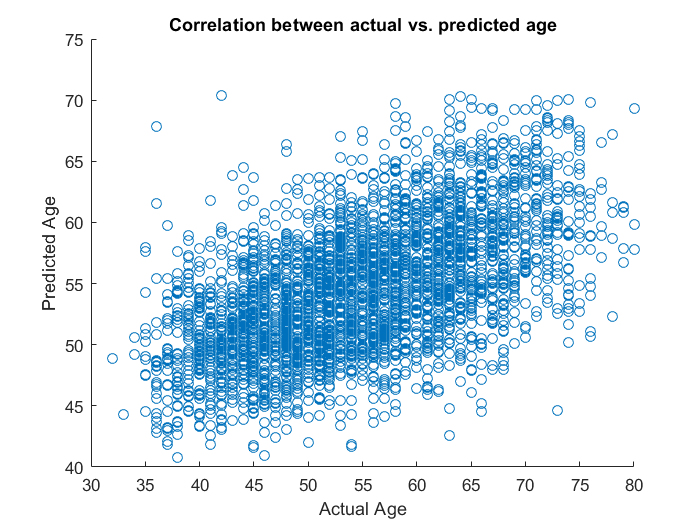

% Visualize scatter plot of actual vs. predicted outcomes
figure
scatter(Ytest, Ypred)
xlabel('Actual Age')
ylabel('Predicted Age')
title('Correlation between actual vs. predicted age')

## Summary

- A random forests model is an ensemble of decision trees that outputs aggregated predictions

- The same set of hyperparameters used with decision trees can be tuned for random forests

- Using random forests, we can assess feature importance, or how much each feature contributes to the model's predictions

### Built-in MATLAB functions introduced in this lesson:

- `TreeBagger`:         develops a random forests model using bootstrap sampling

- `oobError`:             calculates the out-of-bag (OOB) error for each tree added into the RF model

- `fitcensemble`:     develops a classification-based random forests model 

- `fitrensemble`:     develops a regression-based random forests model